# Image Reconstruction from Dichromatic Cone Mosaic

## Construct dichromatic cone mosaic

% generate human cone mosaic with optics
imageSize = [100, 100, 3];
display = load('display.mat');
prior   = load('sparsePrior.mat');

retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', 1.0, 'display', display.CRT12BitDisplay, 'pupilSize', 2.5);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 225.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.648560, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 225.00 230.54 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustm

% change all M cone to L cone
retina.reassignCone(0.0, retina.M_Cone_Idx, retina.L_Cone_Idx, false);

[L, M, S] = retina.coneCount();
fprintf('Number of cones: L - %d, M - %d, S - %d \n', L, M, S);

Number of cones: L - 11046, M - 0, S - 378 


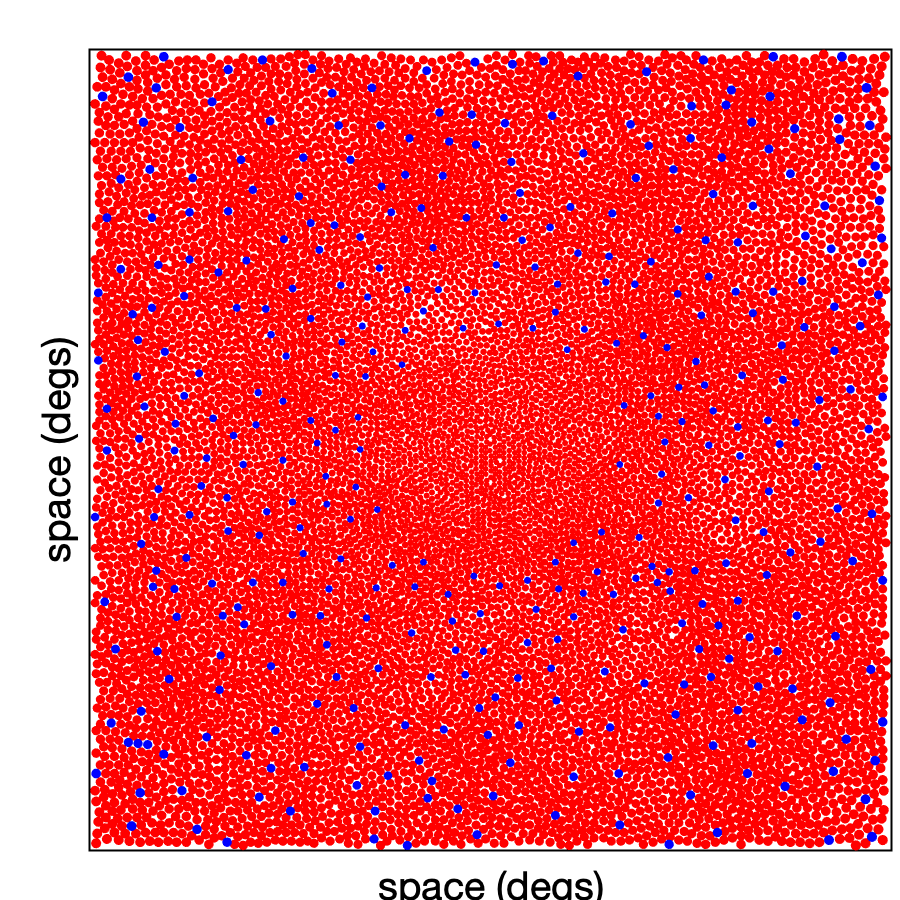

retina.visualizeMosaic();
set(gcf,'position',[0, 0, 450, 450]);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


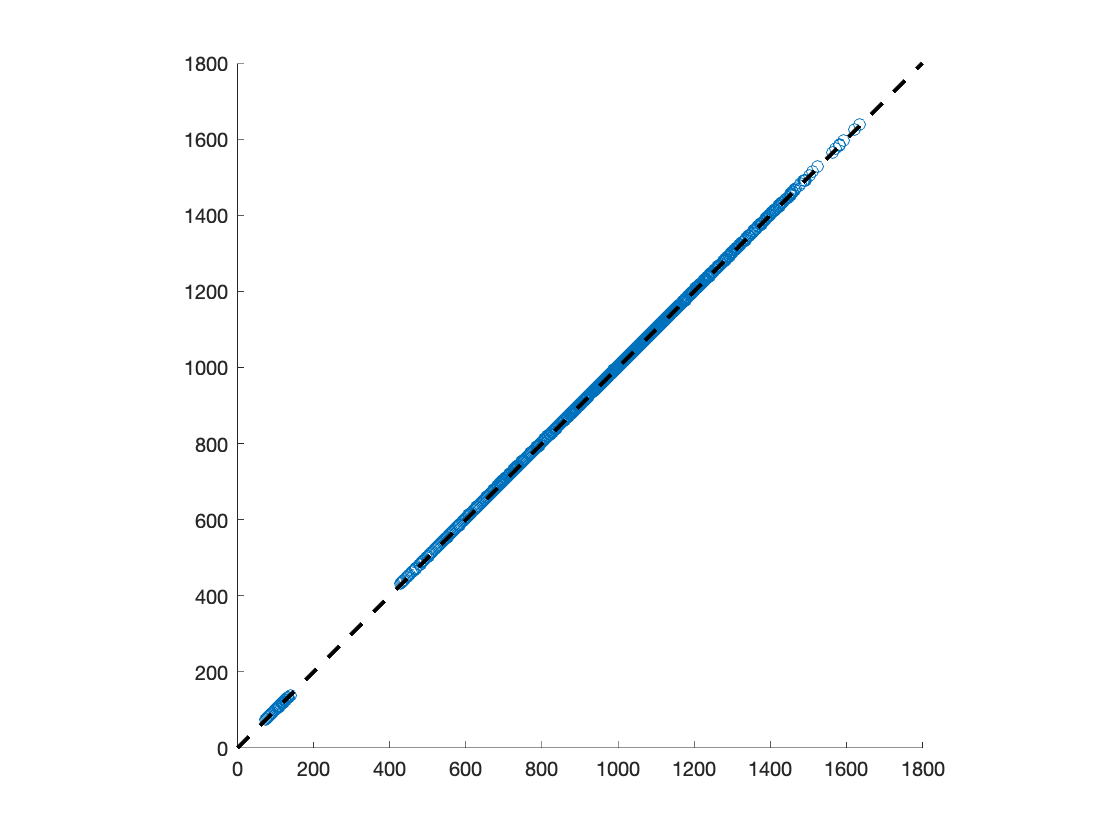

% compute render matrix to represent the
% ISETBio calculation as a linear transformation;
% the render matrix is used to compute likelihood
% in our reconstruction computation (see Methods)

% note that this process is computation-intense
% reduce image size and retina mosaic size (deg)
% if you would like the process to be faster
render = retina.forwardRender(imageSize);

render = double(render);

## Load some example images

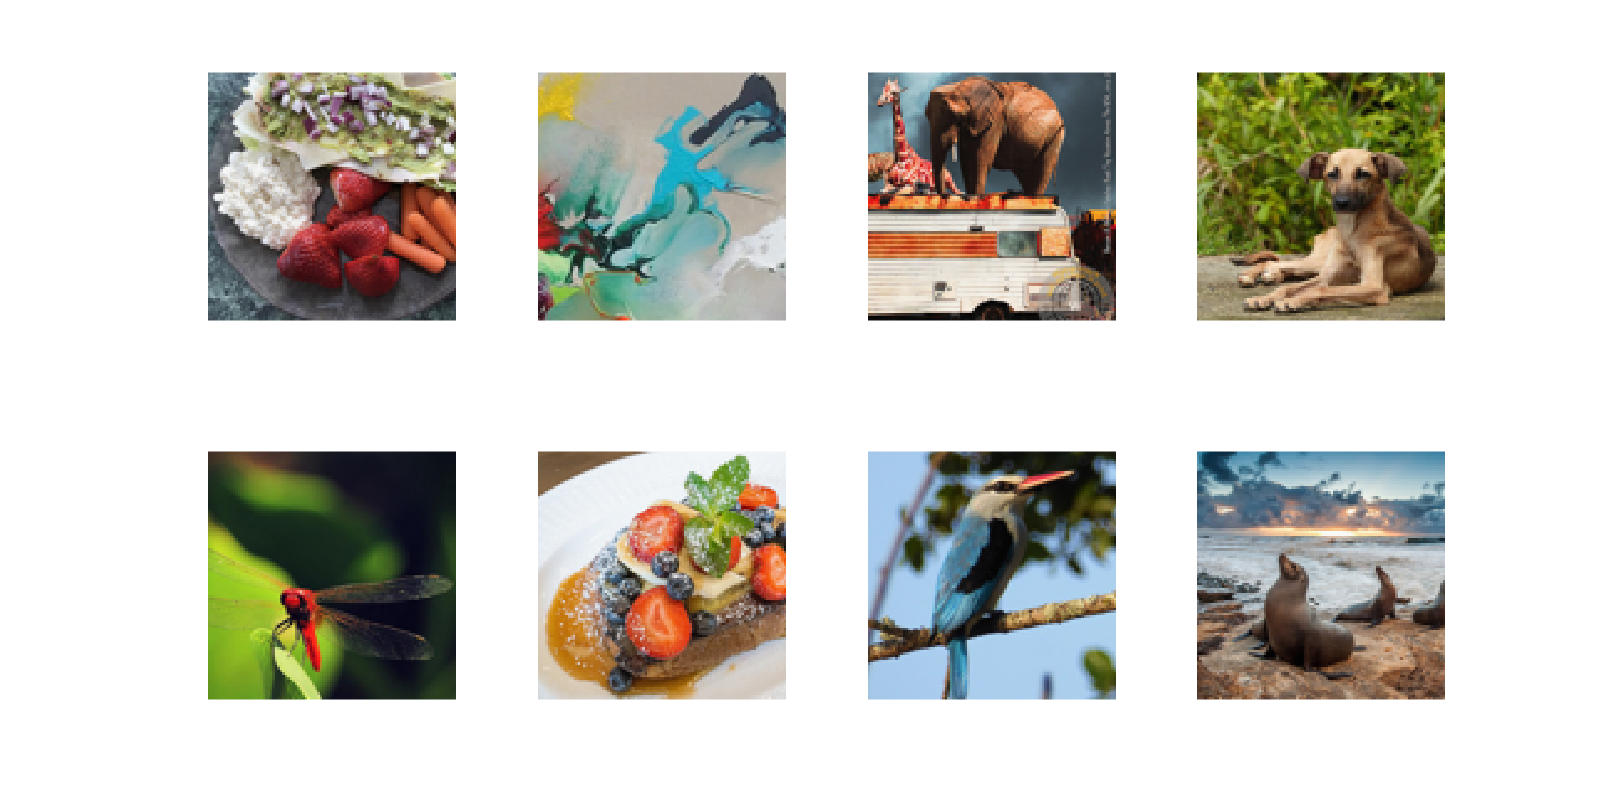

nImage = 8;
input = zeros([nImage, imageSize]);

figure();
fileType = '.jpeg';
for idx = 1:nImage
    fileName = strcat(num2str(idx), fileType);
    filePath = fullfile('.', 'images', fileName);
    image = imresize(im2double(imread(filePath)), 0.30);
    
    image = sampleImage(image, imageSize(1));
    image = image - min(image(:));
    image = image ./ max(image(:));    
    input(idx, :, :, :) = image;
    
    subplot(2, 4, idx);
    imshow(image, 'InitialMagnification', 200);
end
set(gcf,'position',[0, 0, 800, 400]);

## Run image reconstruction

% build an image reconstruction object with sparse prior
regConst = 5e-4; stride = 4;
estimator = ...
    PoissonSparseEstimator(render, inv(prior.regBasis), prior.mu', regConst, stride, imageSize);

% run reconstruction on cone response to each images
% reconstructed images are in linear pixel space, need to 
% gamma correct them before visulization
nIter = 750; bounded = true;
output = zeros([nImage, imageSize]);
parfor idx = 1:nImage
    [~, ~, ~, coneRespVec] = retina.compute(reshape(input(idx, :, :, :), imageSize));
    recon = estimator.estimate(coneRespVec, nIter, rand([prod(imageSize), 1]), bounded, 1.0, 'final');
    output(idx, :, :, :) = gammaCorrection(recon, display.CRT12BitDisplay);
end


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.50000

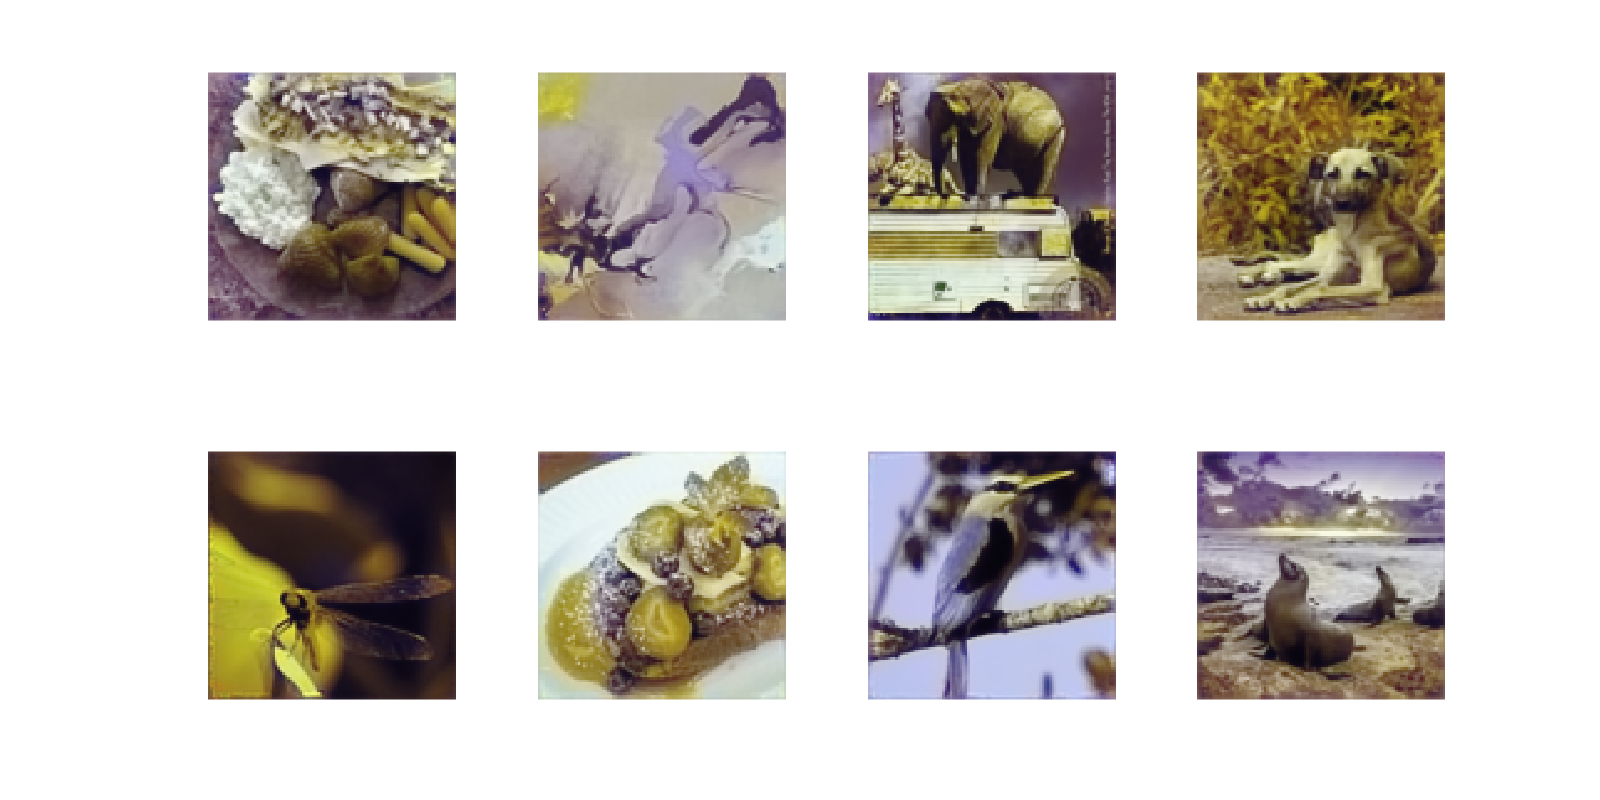

% show reconstructed images
figure();
for idx = 1:nImage
    subplot(2, 4, idx);
    imshow(reshape(output(idx, :, :, :), imageSize), 'InitialMagnification', 200);
end
set(gcf,'position',[0, 0, 800, 400]);

## Repeat the analysis with a different prior to make sure the result is stable

% run reconstruction
prior = load('sparsePrior_0.mat');
estimator = ...
    PoissonSparseEstimator(render, inv(prior.regBasis), prior.mu', regConst, stride, imageSize);

output = zeros([nImage, imageSize]);
parfor idx = 1:nImage
    [~, ~, ~, coneRespVec] = retina.compute(reshape(input(idx, :, :, :), imageSize));
    recon = estimator.estimate(coneRespVec, nIter, rand([prod(imageSize), 1]), bounded, 1.0, 'final');
    output(idx, :, :, :) = gammaCorrection(recon, display.CRT12BitDisplay);
end


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.500000e+02.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 7.50000

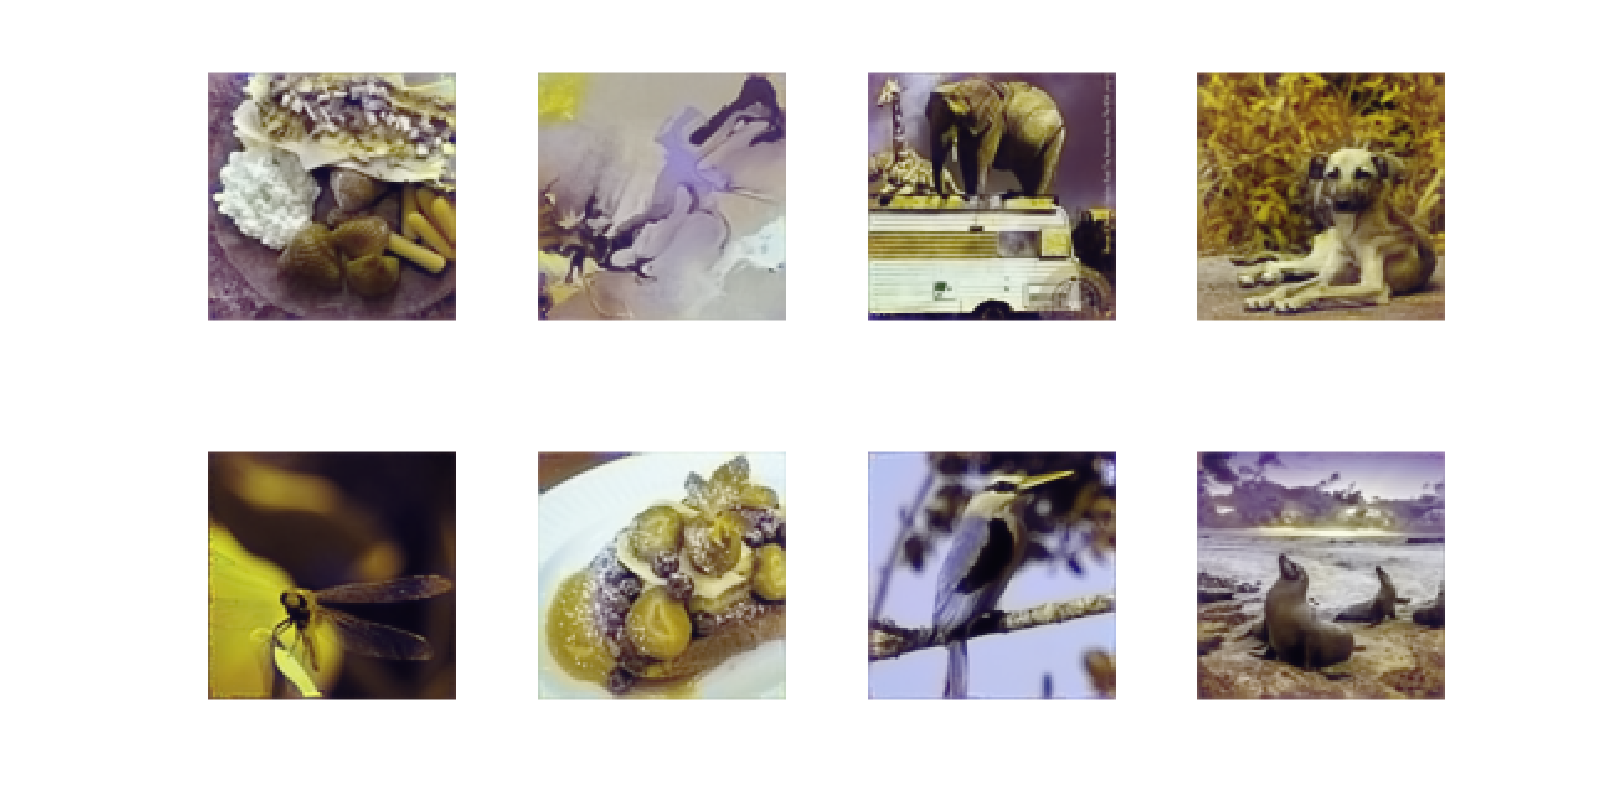

% show reconstructed images
figure();
for idx = 1:nImage
    subplot(2, 4, idx);
    imshow(reshape(output(idx, :, :, :), imageSize), 'InitialMagnification', 200);
end
set(gcf,'position',[0, 0, 800, 400]);